# Phony

A phonetic analysis script by Marie Grevil.

## Getting started

Simply place the audio files to analyze in the subfolder `\Input`, then run the script.

clear all;
 
DEBUG = true;
DEBUG_FILE = 1;
DEBUG_FRAME = 295;

## Settings

A number of settings below can be changed for testing or to better suit your needs.

### Frame

When analyzing an audio file, the data is split up into smaller sections called frames, which allows for frequency analysis at a certain point in time.

#### Frame length

This defines the length of each frame in milliseconds. A shorter frame reduces interference from nearby points in time at the expense of frequency range. A longer frame increases frequency range at the expense of precision.

stng_flo = false;
stng_flv = 20;

#### Frame overlap

To ensure that no information is lost between frames, it is recommended to overlap them by a percentage. A larger overlap results in a smoother transition between frames at the expense of longer computation time.

stng_foo = false;
stng_fov = 0.9;

### Pre-emphasis filter

...

#### Coefficient

...

stng_peo = false;
stng_pev = 0.68;

### Formants

...

#### Linear prediction order

...

stng_lpo = false;
stng_lpv = 16;

### Pitch

...

stng_pio = false;
stng_piv = [2.2 12.5];

### Path

By default, input files are read from the subfolder `\Input`, and output files are written to the subfolder `\Output`. You can customize the paths by activating the corresponding checkbox and entering an exact path in the field. Unchecking the box will result in default path selection regardless of what is written in the field.

#### Custom input path

stng_cio = false;
stng_cip = "";

#### Custom output path

stng_coo = false;
stng_cop = "";

`~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~^~`

## Preparation

### Frame length

if (stng_flo)
    FrameLengthMillis = stng_flv;
else
    FrameLengthMillis = 20;
end
if (DEBUG)
    FrameLengthMillis
end

FrameLengthMillis = 20

clear stng_flo stng_flv

### Frame step

if (stng_foo)
    FrameOverlap = stng_fov;
else
    FrameOverlap = 0.5;
end
FrameStepMillis = FrameLengthMillis*(1-FrameOverlap);
if (DEBUG)
    FrameStepMillis
end

FrameStepMillis = 10

clear stng_foo stng_fov

### Pre-emphasis coefficient

if (stng_peo)
    PreEmphCoeff = stng_pev;
else
    PreEmphCoeff = 0.68;
end
if (DEBUG)
    PreEmphCoeff
end

PreEmphCoeff = 0.6800

clear stng_peo stng_pev

### Linear prediction order

if (stng_lpo)
    LinPredOrder = stng_lpv;
else
    LinPredOrder = 16;
end
if (DEBUG)
    LinPredOrder
end

LinPredOrder = 16

clear stng_lpo stng_lpv

### Pitch

if (stng_pio)
    PitchBoundMillis = stng_piv;
else
    PitchBoundMillis = [2.2 12.5];
end
if (DEBUG)
    PitchBoundMillis
end

PitchBoundMillis =     2.2000   12.5000


clear stng_pio stng_piv

### Input path

This alerts the user and ends the script if a custom path does not exist.

if (stng_cio)
    if exist(stng_cip, "dir")
        InputPath = stng_cip;
    else
        msgbox("Custom input path does not exist.", "Error", "error");
        return
    end
else
    InputPath = pwd+"\Input";
end
if (stng_coo)
    if exist(stng_cop, "dir")
        OutputPath = stng_cop;
    else
        msgbox("Custom output path does not exist.", "Error", "error");
        return
    end
else
    OutputPath = pwd+"\Output";
end
if (DEBUG)
    InputPath
    OutputPath
end

InputPath = "A:\Documents\Marie\Diplom\Phony\Input"

OutputPath = "A:\Documents\Marie\Diplom\Phony\Output"

clear stng_cio stng_cip stng_coo stng_cop

### Input files

% https://www.mathworks.com/help/matlab/import_export/supported-video-file-formats.html
InputFormats = ["*.aifc", "*.aiff", "*.aif", "*.au", "*.flac", "*.ogg", "*.opus", "*.wav", "*.mp3", "*.m4a", "*.mp4"];
InputFiles = [];
for FormatIndex = 1:length(InputFormats)
    TempFiles = dir(fullfile(InputPath, InputFormats(FormatIndex)));
    for FileIndex = 1:height(TempFiles)
        InputFiles = [InputFiles convertCharsToStrings(TempFiles(FileIndex).name)];
    end
end
if (DEBUG)
    InputFiles
end

InputFiles = "english29.wav"

clear InputFormats TempFiles

## Analysis

### Audio import

for FileIndex = 1:length(InputFiles)
    FileContent = importdata(fullfile(InputPath+'\'+InputFiles(FileIndex)));
    SampleRate = FileContent.fs;
    NumSamples = height(FileContent.data); % samples
    if (width(FileContent.data) == 1)
        RawAudio = FileContent.data;
    else
        RawAudio = zeros(NumSamples, 1);
        for SampleIndex = 1:NumSamples
            RawAudio(SampleIndex) = mean(FileContent.data(SampleIndex, :));
        end
    end
    if (DEBUG && FileIndex == DEBUG_FILE)
        disp("File = "+InputFiles(FileIndex))
        RawAudio
    end
    clear FileContent

### Discrete variables

    FrameLength = floor(SampleRate*FrameLengthMillis/1000); % samples
    FrameStep = floor(SampleRate*FrameStepMillis/1000); % samples
    FFTLength = 2^(ceil(log2(FrameLength))); % samples
    FreqRes = SampleRate/FFTLength; % [Hz]
    QuefRes = 1000/SampleRate; % [ms]
    PitchBound = round(PitchBoundMillis./QuefRes); % sample index
    NumFrames = floor((NumSamples-FrameLength+FrameStep)/FrameStep); % frames
    if (DEBUG && FileIndex == DEBUG_FILE)
        FrameLength
        FrameStep
        FFTLength
        FreqRes
        QuefRes
        PitchBound
        NumFrames
    end

### Output arrays

    File_ZeroCrossRate = zeros(1, NumFrames);
    File_ShortTimeEnergy = zeros(1, NumFrames);
    File_PitchFreq = zeros(1, NumFrames);
    File_PitchRatio = zeros(1, NumFrames);
    File_Spectrum = zeros(FFTLength/2, NumFrames);
    File_LinPredSSE = zeros(1, NumFrames);
    File_Formants = zeros(LinPredOrder/2, NumFrames);
    File_LinPredCoeffs = zeros(LinPredOrder, NumFrames);
    File_LinPredRoots = zeros(LinPredOrder-1, NumFrames);

### Window function

    Window = zeros(FrameLength, 1);
    for SampleIndex = 1:FrameLength
        Window(SampleIndex) = 0.5*(1-cos(2*pi*(SampleIndex-1)/(FrameLength-1)));
    end
    if (DEBUG && FileIndex == DEBUG_FILE)
        Window
    end

### Frame

    for FrameIndex = 1:NumFrames
        DataOffset = (FrameIndex-1)*FrameStep;
        RawFrame = RawAudio(DataOffset+1:DataOffset+FrameLength);
        if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
            DataOffset
            RawFrame
        end

#### Zero-crossing rate

        RawMean = mean(RawFrame);
        SignFrame = zeros(FrameLength, 1);
        for SampleIndex = 1:FrameLength
            if (RawFrame(SampleIndex)-RawMean < 0)
                SignFrame(SampleIndex) = 1;
            end
        end
        ZeroCrossCount = 0;
        for SampleIndex = 1:FrameLength-1
            if (SignFrame(SampleIndex)+SignFrame(SampleIndex+1) == 1)
                ZeroCrossCount = ZeroCrossCount+1;
            end
        end
        File_ZeroCrossRate(FrameIndex) = ZeroCrossCount*SampleRate/(2*FrameLength);
        if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
            RawMean
            SignFrame
            ZeroCrossCount
            disp("ZeroCrossRate = "+File_ZeroCrossRate(FrameIndex))
            taxi = RawFrame-RawMean;
        end
        clear RawMean SignFrame ZeroCrossCount

#### Pre-emphasis

        EmphFrame = zeros(FrameLength, 1);
        if (FrameIndex == 1)
            PreEmphCarry = 0;
        else
            PreEmphCarry = RawAudio(DataOffset);
        end
        for SampleIndex = 1:FrameLength
            if (SampleIndex == 1)
                EmphFrame(SampleIndex) = RawFrame(SampleIndex)-PreEmphCoeff*PreEmphCarry;
            else
                EmphFrame(SampleIndex) = RawFrame(SampleIndex)-PreEmphCoeff*RawFrame(SampleIndex-1);
            end
        end
        if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
            PreEmphCarry
            EmphFrame
        end
        clear PreEmphCarry

#### Window

        WinFrame = zeros(FrameLength, 1);
        for SampleIndex = 1:FrameLength
            WinFrame(SampleIndex) = Window(SampleIndex)*EmphFrame(SampleIndex);
        end
        if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
            WinFrame
        end
        clear EmphFrame;

#### Short time energy

        File_ShortTimeEnergy(FrameIndex) = mean(WinFrame.^2);
        if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
            disp("ShortTimeEnergy = "+File_ShortTimeEnergy(FrameIndex))
        end

#### FFT

        PadFrame = zeros(FFTLength, 1);
        PadFrame(1:FrameLength) = WinFrame;
        FreqFrame = phonyFFT(PadFrame)/FFTLength;
        if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
            PadFrame
            FreqFrame
        end
        File_Spectrum(:, FrameIndex) = FreqFrame((end/2)+1:end);
        clear PadFrame

#### Pitch

%         QuefFrame = abs(dct(log(abs(FreqFrame).^2)));
%         PitchFilterQ = 0.1; % Process noise.
%         PitchFilterR = 1; % Detection error.
%         PitchFilterEstX = 0;
%         PitchFilterEstP = 100;
%         PitchFilterPredX = PitchFilterEstX;
%         PitchFilterPredP = PitchFilterEstP+PitchFilterQ;
%         PitchVal = -1;
%         PitchIndex = PitchBound(1);
%         for SampleIndex = 1:PitchBound(2)
%             PitchFilterK = PitchFilterPredP/(PitchFilterPredP+PitchFilterR);
%             PitchFilterEstX = PitchFilterPredX+PitchFilterK*(QuefFrame(SampleIndex)-PitchFilterPredX);
%             PitchFilterEstP = (1-PitchFilterK)*PitchFilterPredP;
%             PitchFilterPredX = PitchFilterEstX;
%             PitchFilterPredP = PitchFilterEstP+PitchFilterQ;
%             if (SampleIndex >= PitchBound(1) && PitchFilterEstX > (1-(SampleIndex-PitchIndex)/SampleIndex/10)*PitchVal)
%                 %if (SampleIndex >= PitchBound(1) && QuefFrame(SampleIndex) > PitchVal)
%                 PitchVal = PitchFilterEstX;
%                 PitchIndex = SampleIndex;
%             end
%         end
%         File_PitchRatio(FrameIndex) = PitchVal/mean(QuefFrame(PitchBound(1):PitchBound(2)));
%         File_PitchFreq(FrameIndex) = 1000/((PitchIndex-1)*QuefRes);
%         if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
%             QuefFrame
%             PitchVal
%             PitchIndex
%             disp("PitchRatio = "+File_PitchRatio(FrameIndex))
%             PitchQuef = (PitchIndex-1)*QuefRes;
%             disp("PitchFreq = "+File_PitchFreq(FrameIndex))
%             pitch_test = QuefFrame;
%             pitch_bound = PitchBound;
%             quef_res = QuefRes;
%         end
%         clear QuefFrame PitchVal PitchIndex PitchQuef

#### Linear prediction

        LinPredCoeffs = zeros(LinPredOrder, 1);
        if (sum(abs(WinFrame)) ~= 0)
            LinPredY = WinFrame(LinPredOrder+1:FrameLength);
            LinPredX = zeros(FrameLength-LinPredOrder, LinPredOrder);
            for OrderIndex = 1:LinPredOrder
                LinPredX(:, OrderIndex) = WinFrame(LinPredOrder+1-OrderIndex:FrameLength-OrderIndex);
            end
            LinPredCoeffs = (transpose(LinPredX)*LinPredX)\(transpose(LinPredX)*LinPredY);
            Prediction = zeros(FrameLength-LinPredOrder, 1);
            Residual = zeros(FrameLength-LinPredOrder, 1);
            for SampleIndex = 1:(FrameLength-LinPredOrder)
                [Prediction(SampleIndex), Residual(SampleIndex)] = phonyLPC(LinPredX(SampleIndex, :), LinPredY(SampleIndex), LinPredCoeffs);
            end
            File_LinPredSSE(FrameIndex) = transpose(Residual)*Residual;
            File_LinPredCoeffs(:, FrameIndex) = LinPredCoeffs;
            if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
                LinPredY
                LinPredX
                LinPredTransX = transpose(LinPredX)
                LinPredXX = transpose(LinPredX)*LinPredX
                LinPredXY = LinPredTransX*LinPredY
                LinPredCoeffs
                Prediction
                Residual
                disp("LinPredSSE = "+File_LinPredSSE(FrameIndex))
                clear LinPredTransX LinPredXX LinPredXY
            end
            clear LinPredY LinPredX Prediction Residual
        end

#### Formants

        if (sum(abs(LinPredCoeffs)) ~= 0)
            LinPredCoeffs(LinPredOrder) = [];
            LinPredCoeffs = [1 -LinPredCoeffs'];
            LinPredRoots = roots(LinPredCoeffs);
            File_LinPredRoots(:, FrameIndex) = LinPredRoots;
            LinPredRoots = LinPredRoots(imag(LinPredRoots) >= 0);
            LinPredRootFreq = atan2(imag(LinPredRoots), real(LinPredRoots)).*(SampleRate/(2*pi));
            LinPredRootBW = -(SampleRate*log(abs(LinPredRoots)))/(4*pi);
            FormantIndex = 0;
            for RootIndex = 1:length(LinPredRoots)
                if (LinPredRootFreq(RootIndex) > 90 && LinPredRootBW(RootIndex) < 400)
                    FormantIndex = FormantIndex+1;
                    File_Formants(FormantIndex, FrameIndex) = LinPredRootFreq(RootIndex);
                end
            end
            if (DEBUG && FileIndex == DEBUG_FILE && FrameIndex == DEBUG_FRAME)
                LinPredCoeffs
                LinPredRoots
                LinPredRootFreq
                LinPredRootBW
                disp("Formants = "+File_Formants(:, FrameIndex))
            end
            clear LinPredCoeffs LinPredRoots LinPredRootFreq LinPredRootBW FormantIndex
        end

End frame analysis.

        clear RawFrame FreqFrame WinFrame DataOffset
    end

### Graphs

    Suffix = ['FL' num2str(FrameLengthMillis) '_FO' num2str(FrameOverlap*100) '_PE' num2str(PreEmphCoeff*100) '_LP' num2str(LinPredOrder) '_PB' num2str(PitchBoundMillis(1)*10) '_' num2str(PitchBoundMillis(2)*10)];

#### Spectrum

    figure
    ImageData = uint8(255*mat2gray(log10(abs(File_Spectrum))));
    ImageFile = fullfile(OutputPath+'\'+InputFiles(FileIndex)+'_Spectrum_'+Suffix+'.bmp');
    if (isfile(ImageFile))
        delete(ImageFile);
    end
    imwrite(ImageData, ImageFile);
    imshow(ImageFile)
    %figure
    %face_uint8 = uint8(255*)

#### Zero cross rate

    figure
    plot(log10(File_ZeroCrossRate))

#### Short time energy

    figure
    plot(log10(File_ShortTimeEnergy))

#### Pitch ratio

    %     figure
    %     plot(log10(File_PitchRatio))

#### Pitch frequency

    %     figure
    %     plot(log10(File_PitchFreq))

#### Linear prediction sum of square errors

    figure
    plot(log10(File_LinPredSSE))

End file analysis.

File = english29.wav


RawAudio =     0.0000
   -0.0000
    0.0000
    0.0000
         0
         0
   -0.0000
    0.0001
         0
   -0.0000


FrameLength = 882

FrameStep = 441

FFTLength = 1024

FreqRes = 43.0664

QuefRes = 0.0227

PitchBound =     97   551


NumFrames = 3254

Window =          0
    0.0000
    0.0001
    0.0001
    0.0002
    0.0003
    0.0005
    0.0006
    0.0008
    0.0010


DataOffset = 129654

RawFrame =     0.1036
    0.1034
    0.1013
    0.1060
    0.1176
    0.1227
    0.1154
    0.1113
    0.1248
    0.1438


RawMean = -0.0062

SignFrame =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ZeroCrossCount = 18

ZeroCrossRate = 450


PreEmphCarry = 0.0980

EmphFrame =     0.0370
    0.0330
    0.0309
    0.0372
    0.0455
    0.0427
    0.0320
    0.0328
    0.0492
    0.0589


WinFrame =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001


ShortTimeEnergy = 0.0004528


PadFrame =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001


FreqFrame =    0.0000 + 0.0000i
   0.0001 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0008 - 0.0031i
  -0.0052 + 0.0060i
   0.0066 - 0.0028i
  -0.0023 - 0.0002i
   0.0003 + 0.0002i
  -0.0011 - 0.0015i


LinPredY =    -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0000
    0.0001
    0.0000
   -0.0001


LinPredX =     0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
   -0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0001   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000
   -0.0001   -0.0001   

LinPredTransX =     0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0000    0.0001    0.0000   -0.0001   -0.0001   -0.0000    0.0000   -0.0001   -0.0003   -0.0003   -0.0002   -0.0004   -0.0007   -0.0009   -0.0009   -0.0009   -0.0011   -0.0014   -0.0016   -0.0014   -0.0013   -0.0014   -0.0015   -0.0014   -0.0013   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0024   -0.0028   -0.0031   -0.0033   -0.0034   -0.0035   -0.0036   -0.0036   -0.0037   -0.0038   -0.0036   -0.0033   -0.0030
    0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0000    0.0001    0.0000   -0.0001   -0.0001   -0.0000    0.0000   -0.0001   -0.0003   -0.0003   -0.0002   -0.0004   -0.0007   -0.0009   -0.0009   -0.0009   -0.0011   -0.0014   -0.0016   -0.0014   -0.0013   -0.0014   -0.0015   -0.0014   -0.0013   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0024   -0.0028   -0.0031   -0.0033   -0.0034   -0.0035   -0.0036   -0.0036   -0.0037   -0.0038   

LinPredXX =     0.3994    0.3952    0.3868    0.3800    0.3741    0.3644    0.3509    0.3387    0.3311    0.3254    0.3175    0.3080    0.3013    0.2989    0.2964    0.2902
    0.3952    0.3994    0.3952    0.3868    0.3800    0.3741    0.3644    0.3509    0.3387    0.3311    0.3254    0.3175    0.3080    0.3013    0.2989    0.2964
    0.3868    0.3952    0.3994    0.3952    0.3868    0.3800    0.3741    0.3644    0.3509    0.3387    0.3311    0.3254    0.3175    0.3080    0.3013    0.2989
    0.3800    0.3868    0.3952    0.3994    0.3952    0.3868    0.3800    0.3741    0.3644    0.3509    0.3387    0.3311    0.3254    0.3175    0.3080    0.3013
    0.3741    0.3800    0.3868    0.3952    0.3994    0.3952    0.3868    0.3800    0.3741    0.3644    0.3509    0.3387    0.3311    0.3254    0.3175    0.3080
    0.3644    0.3741    0.3800    0.3868    0.3952    0.3994    0.3952    0.3868    0.3800    0.3741    0.3644    0.3509    0.3387    0.3311    0.3254    0.3175
    0.3509    0.3644  

LinPredXY =     0.3952
    0.3868
    0.3800
    0.3741
    0.3644
    0.3509
    0.3387
    0.3311
    0.3254
    0.3175


LinPredCoeffs =     3.9777
   -8.3826
   12.6037
  -14.0973
   11.3248
   -5.4295
   -0.9420
    4.9735
   -5.2575
    2.9324


Prediction =    -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0001
   -0.0000
    0.0001
    0.0001
   -0.0001


Residual =     0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


LinPredSSE = 0.00012751


LinPredCoeffs =     1.0000   -3.9777    8.3826  -12.6037   14.0973  -11.3248    5.4295    0.9420   -4.9735    5.2575   -2.9324    0.1791    1.5664   -1.9219    1.3777   -0.6856


LinPredRoots =    1.1583 + 0.0000i
   1.0686 + 0.3229i
   0.8420 + 0.6136i
  -0.7592 + 0.1852i
   0.4550 + 0.8462i
   0.2064 + 1.0203i
  -0.1590 + 0.9885i
  -0.2442 + 0.8094i


LinPredRootFreq = 	1.0e+04 *

         0
    0.2060
    0.4420
    2.0371
    0.7562
    0.9624
    1.2144
    1.3081


LinPredRootBW =  -515.7836
 -386.1685
 -143.9463
  865.4861
  140.5519
 -140.7949
   -4.1219
  589.3174


    "Formants = 2059.55724"
    "Formants = 4420.13155"
    "Formants = 7562.42809"
    "Formants = 9623.91738"
    "Formants = 12144.3639"
    "Formants = 0"
    "Formants = 0"
    "Formants = 0"



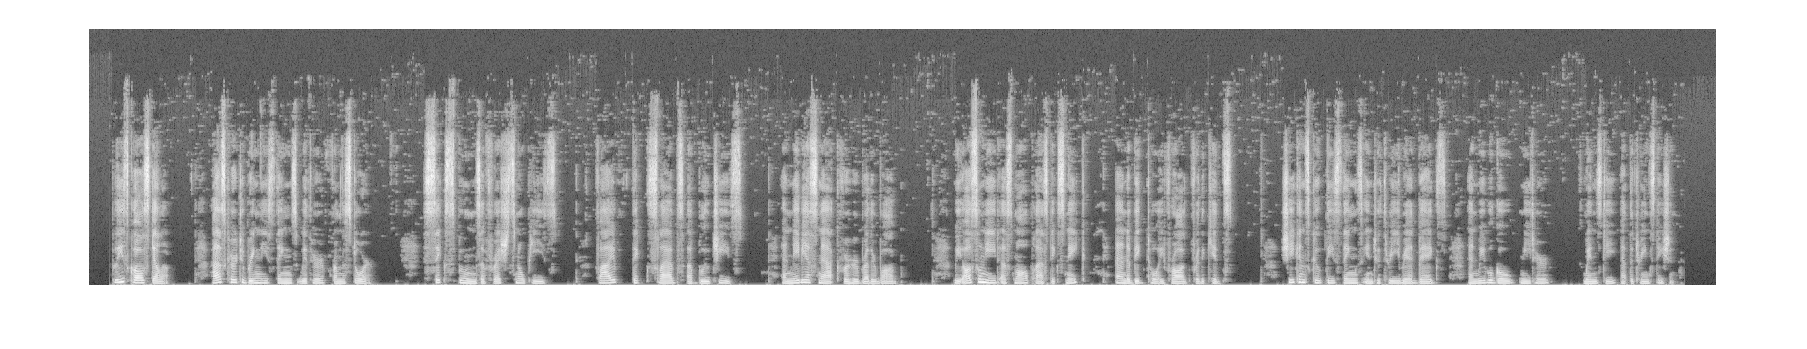

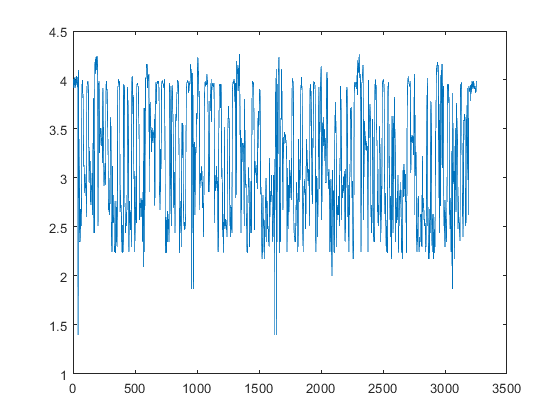

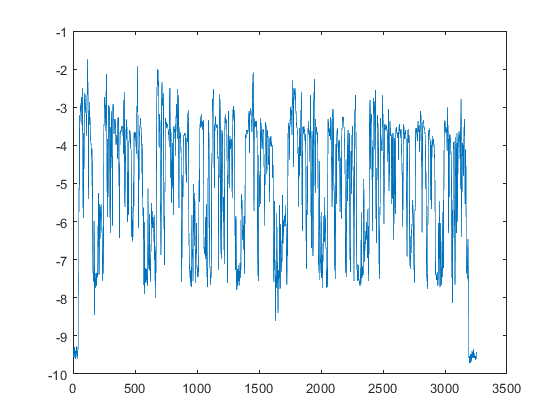

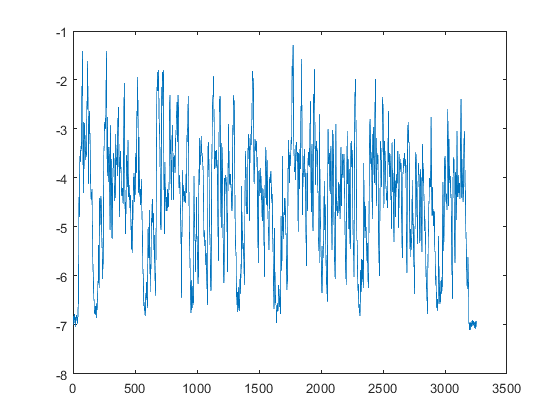

    clear RawAudio NumFrames NumSamples Window PitchBound QuefRes %FreqRes
    clear SampleRate FFTLength FrameLength FrameStep
end

clear FormatIndex FrameIndex FileIndex SampleIndex InputFiles InputPath RootIndex OrderIndex
clear FrameLengthMillis FrameStepMillis LinPredOrder PreEmphCoeff PitchBoundMillis FrameOverlap
clear DEBUG DEBUG_FILE DEBUG_FRAME



clear ImageData ImageFile

figure
ImageData = zeros(height(File_Spectrum), width(File_Spectrum));
for FrameIndex = 1:width(File_Spectrum)
    ImageData(:, FrameIndex) = uint8(255*mat2gray(abs(File_Spectrum(:, FrameIndex))));
end
ImageData = ind2rgb(ImageData, parula);
ImageFile = fullfile(OutputPath+'\'+'test'+'_Spectrum_'+Suffix+'.png');
if (isfile(ImageFile))
    delete(ImageFile);
end
%imwrite(ImageData, ImageFile);
%imshow(ImageFile)




Gather = [];
%Gather2 = [];
Gather3 = [];

for FrameIndex = 1:width(File_Spectrum)
    if (File_ZeroCrossRate(FrameIndex) > 0)
        TempIndex3 = 512-floor(File_ZeroCrossRate(FrameIndex)/FreqRes);
        if (TempIndex3 > 0)
            Gather3 = [Gather3 TempIndex3];
            ImageData(TempIndex3, FrameIndex, :) = [0, 0, 0];
        end
    end
%     if (File_PitchFreq(FrameIndex) > 0)
%         TempIndex2 = 512-floor(File_PitchFreq(FrameIndex)/FreqRes);
%         if (TempIndex2 > 0)
%             disp(FrameIndex)
%             %File_PitchFreq(FrameIndex)
%             %floor(File_PitchFreq(FrameIndex)/FreqRes)
%             %TempIndex2;
%             Gather2 = [Gather2 TempIndex2];
%             ImageData(TempIndex2, FrameIndex, :) = [255, 0, 0];
%         end
%     end
    for FormantIndex = 1:height(File_Formants)
        if (File_Formants(FormantIndex, FrameIndex) > 0)
            TempIndex = 512-floor(File_Formants(FormantIndex, FrameIndex)/FreqRes);
            if (TempIndex > 0)
                Gather = [Gather TempIndex];
                ImageData(TempIndex, FrameIndex, :) = [255, 255, 255];
            end
        end
    end
end
Gather

Gather =     67   167    82    66    68   191   126    64   223   162    91    67   384   310    70   324    70   154   383   191    65    76   131    70    56    99   156   160    73   162   148    71   159   217    73    65   161    66   128   192    60    70    61   118    64   285   215   308   185    67


max(Gather)

ans = 510

min(Gather)

ans = 31

% Gather2
% max(Gather2)
% min(Gather2)
Gather3

Gather3 =    282   297   285   276   304   319   305   320   317   276   273   270   290   307   279   265   298   310   287   287   295   316   319   283   308   293   258   261   268   272   296   287   273   267   284   313   295   313   317   291   512   511   244   271   229   218   498   454   476   482


max(Gather3)

ans = 512

min(Gather3)

ans = 85

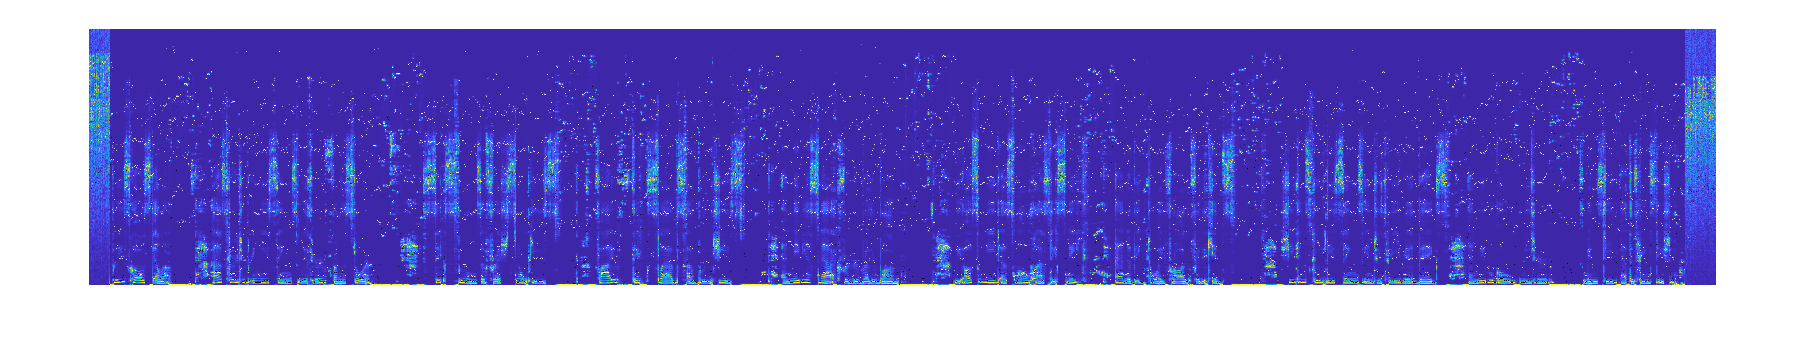

imwrite(ImageData, ImageFile);
imshow(ImageFile)